assert(endsWith(pwd, "ferromagnetic metal disk"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % length (m)
EM.Nturns = 60;

EM.z = 5.00e-3; % (m)

#### Sensor

Sensor.num = 20;
Sensor.side_length = 0.4e-3;

Sensor.position = [linspace(6e-3,30e-3,Sensor.num); 2.5e-3*ones(1,Sensor.num)];

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 30; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.02 seconds


clear disk r z

Model.conductivity = 1.45e6 * ones(1,Model.num_elms); % (S/m)
Model.relative_permeability = 50 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 99.73 seconds


#### Solve in frequency domain

EM.frequency_domain.current = 1; % (A)
EM.frequency_domain.current_density = EM.frequency_domain.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.frequency_domain.frequency = 5000; % (Hz)

[Model, EM, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, EM, Sensor);

solve in frequency domain took 11.23 seconds


#### Plot result

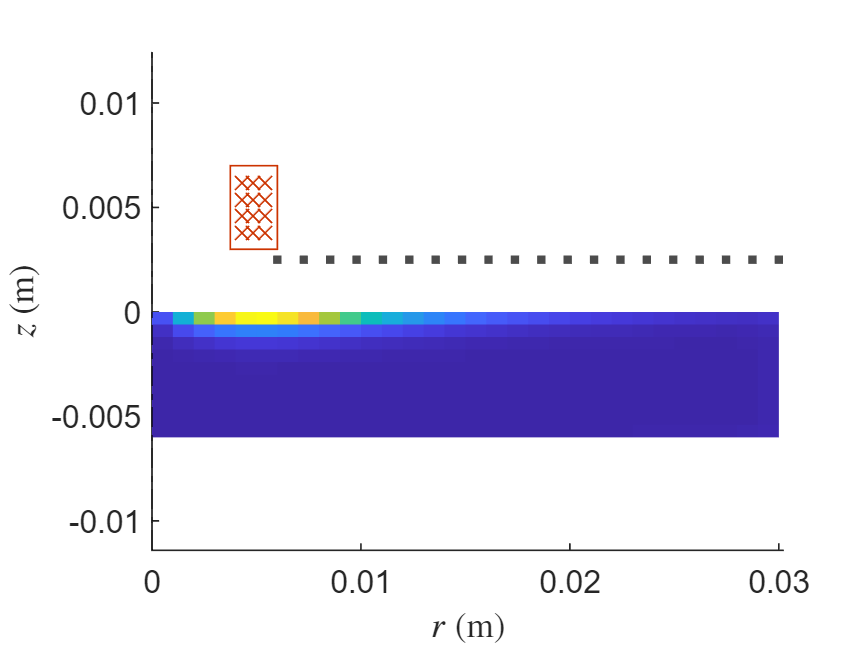

PlotWorld2D(Model, EM, Sensor, abs(Model.frequency_domain.J));

clf

## Compare with FEA

#### Current density

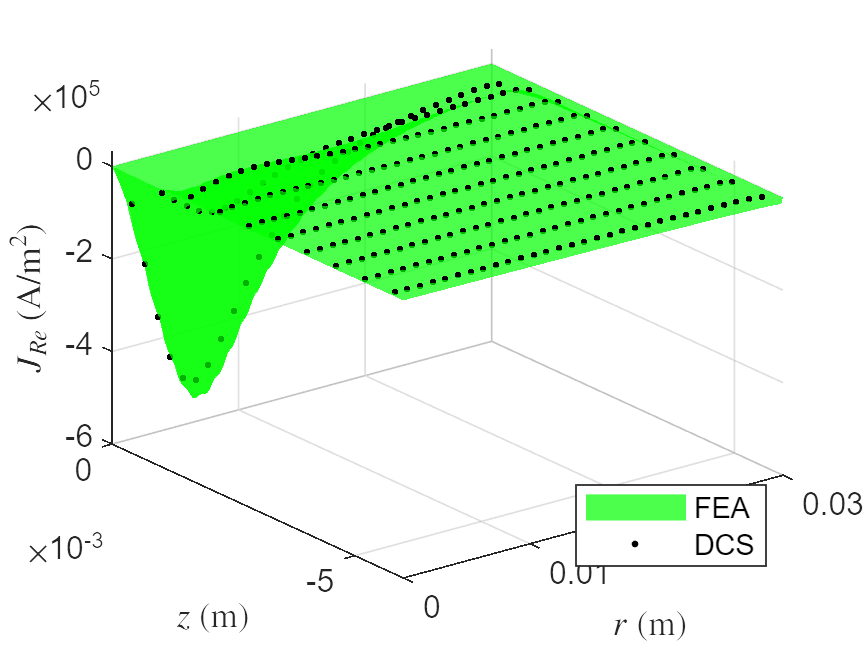

data = readmatrix('FEA_data/J.csv', 'CommentStyle','%');
FEA.r_model = reshape(data(:,1), 200, []);
FEA.z_model = reshape(data(:,2), 200, []);
FEA.J = reshape(data(:,3), 200, []);

surf(FEA.r_model,FEA.z_model, real(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), real(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re}$ (A/m$^2$)", 'Interpreter','latex')
hold off

clf

FEA.J_Re_interpolant = griddedInterpolant(FEA.r_model,FEA.z_model, real(FEA.J));
J_FEA = FEA.J_Re_interpolant(Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = real(Model.frequency_domain.J);
relative_error = mean(abs((J_DSC - J_FEA) ./ J_FEA));
fprintf("average relative error: %f", relative_error)

average relative error: 0.820456

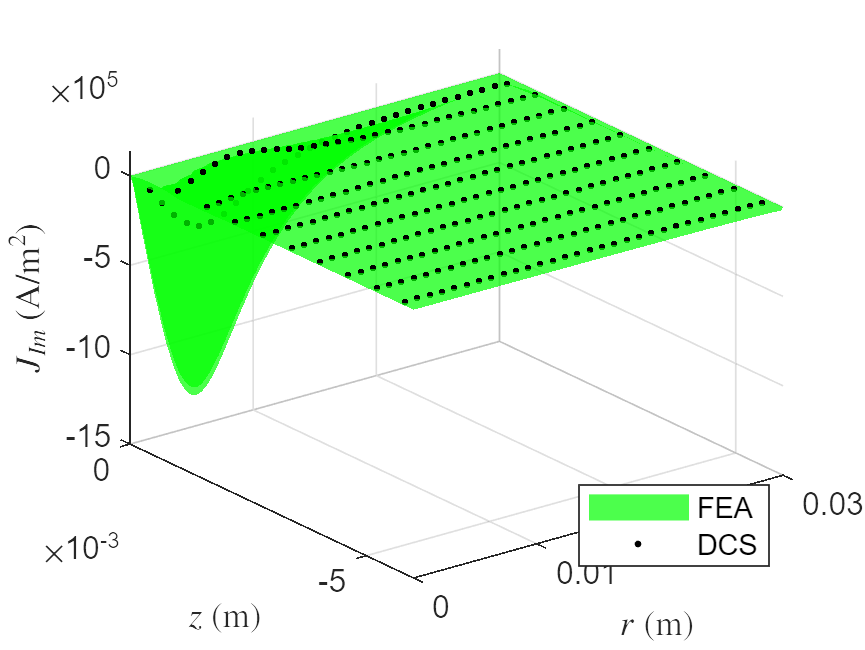


surf(FEA.r_model,FEA.z_model, imag(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), imag(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im}$ (A/m$^2$)", 'Interpreter','latex')
hold off

clf

FEA.J_Im_interpolant = griddedInterpolant(FEA.r_model,FEA.z_model, imag(FEA.J));
J_FEA = FEA.J_Im_interpolant(Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = imag(Model.frequency_domain.J);
relative_error = mean(abs((J_DSC - J_FEA) ./ J_FEA));
fprintf("average relative error: %f", relative_error)

average relative error: 1.163303


clear data J_FEA J_DSC relative_error

#### Magnetic flux density

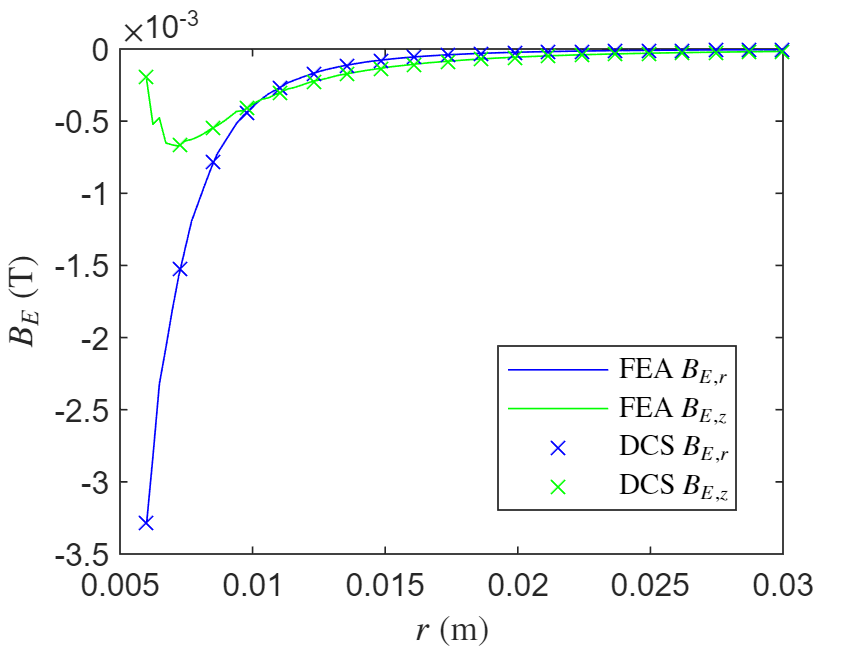

data = readmatrix('FEA_data/B_E.csv', 'CommentStyle','%');
FEA.r_sensor = data(:,1);
FEA.B_E_r = data(:,3);
FEA.B_E_z = data(:,4);
data = readmatrix('FEA_data/B_E_plus_B_C.csv', 'CommentStyle','%');
FEA.r_sensor = data(:,1);
FEA.B_C_r = data(:,3) - FEA.B_E_r;
FEA.B_C_z = data(:,4) - FEA.B_E_z;
clear data

plot(FEA.r_sensor, FEA.B_E_r, 'b-', 'DisplayName','FEA $B_{E,r}$'); hold on
plot(FEA.r_sensor, FEA.B_E_z, 'g-', 'DisplayName','FEA $B_{E,z}$');
plot(Sensor.position(1,:), Sensor.frequency_domain.B_E(1,:), 'bx', 'DisplayName','DCS $B_{E,r}$')
plot(Sensor.position(1,:), Sensor.frequency_domain.B_E(2,:), 'gx' ,'DisplayName','DCS $B_{E,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

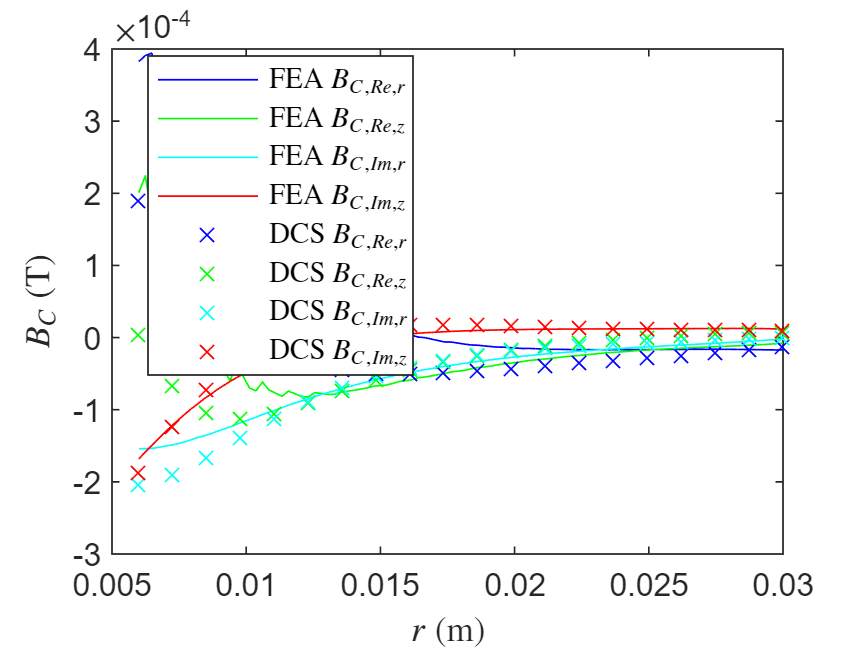

clf

plot(FEA.r_sensor, real(FEA.B_C_r), 'b-', 'DisplayName','FEA $B_{C,Re,r}$'); hold on
plot(FEA.r_sensor, real(FEA.B_C_z), 'g-', 'DisplayName','FEA $B_{C,Re,z}$');
plot(FEA.r_sensor, imag(FEA.B_C_r), 'c-', 'DisplayName','FEA $B_{C,Im,r}$');
plot(FEA.r_sensor, imag(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Im,z}$');
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,r}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'cx', 'DisplayName','DCS $B_{C,Im,r}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'rx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf